# **Controllo della velocità di un veicolo**

Il controllo automatico della velocità di crociera rappresenta un ottimo esempio di controllo in retroazione integrato in numerosi veicoli odierni. La sua principale funzione è quella di mantenere una velocità costante del veicolo anche a fronte di perturbazioni esterne, come le fluttuazioni nelle condizioni del vento o nell'elevazione del tratto stradale. Ciò viene realizzato valutando la velocità attuale del veicolo, confrontandola con la velocità desiderata e quindi modificando autonomamente la posizione dell'acceleratore in base all'algoritmo di controllo.

## Modellazione del sistema

Si consideri una modellazione di base del comportamento del veicolo, come quella rappresentata nel diagramma a corpo libero.

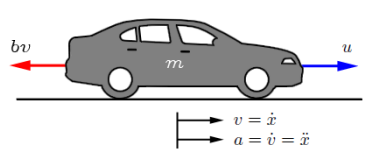

Il veicolo di massa $m$ subisce l'influenza di una forza di controllo che simboleggia la forza generata nel punto di contatto tra gli pneumatici e l'asfalto.

In un modello semplificato di questo tipo, si assume di poter agire direttamente su questa forza non considerando la complessità della trasmissione o delle gomme che contribuiscono a generarla.

Alla forza di controllo si oppone una forza derivante da fattori quali l'attrito dell'aria e del rotolamento, proporzionali alla velocità del veicolo ed agenti nella direzione opposta al suo moto.

Il sistema in questione può essere visto come un sistema SISO a singolo ingresso (la forza di controllo) e singola uscita (la velocità).

### Formulazione matematica

L'equazione che esprime la dinamica del veicolo può essere ottenuta esplicitando la sommatoria delle forze agenti lungo la direzione orizzontale per la seconda legge di Newton:


$$m\dot{v} \left(t\right)+\textrm{bv}\left(t\right)=u\left(t\right)$$


Poiché l'obiettivo è quello di regolare la velocità del veicolo, è ragionevole focalizzarsi su tale quantità. Pertanto:


$$m\dot{y} \left(t\right)+\textrm{by}\left(t\right)=u\left(t\right)$$


### Rappresentazione nello spazio di stato

Considerando la velocità del veicolo come unica variabile di stato, il sistema può essere espresso nella forma:


$$\dot{x} \left(t\right)=-\frac{b}{m}x\left(t\right)+\frac{1}{m}u\left(t\right)$$



$$y\left(t\right)=x\left(t\right)$$


### Funzione di trasferimento

Trasformando secondo Laplace l'equazione che esprime la dinamica del veicolo:


$$\left(\textrm{ms}+b\right)Y\left(s\right)=U\left(s\right)$$


ne consegue la funzione di trasferimento:


$$G\left(s\right)=\frac{Y\left(s\right)}{U\left(s\right)}=\frac{1}{\textrm{ms}+b}$$


## Implementazione del sistema

% Operazioni preliminari
close all;
clear all; 
clc;

### Parametri del sistema

% Massa del veicolo [kg]
m = 1000;

% Coefficiente di smorzamento [Ns/m]
b = 50;

### Matrici del sistema

% Matrici del sistema
A = -b/m;
B = 1/m;
C = 1;
D = 0;

### Definizione del sistema

% Sistema nello spazio di stato
plant_ss = ss(A,B,C,D);

% Funzione di trasferimento
s = tf('s');
plant_tf = 1/(m*s+b);

### Requisiti del sistema

Preliminarmente all'analisi, è buona norma definire alcuni requisiti che si desidera raggiungere nella progettazione del controllore. Considerato che quando il motore esercita una forza di 1000 N il veicolo raggiunge una velocità massima di 20 m/s (cioè 72 km/h), come evidenziato successivamente dalla risposta al gradino in anello aperto, si vuole far accelerare il veicolo in modo che raggiunga tale velocità in meno di 5 secondi.

Per questa specifica applicazione, sono accettabili un overshoot del 10% ed un errore a regime sulla velocità del 2%.

Tenendo a mente queste considerazioni, è possibile formulare i criteri di progettazione per questa problematica:

- Raggiungere un tempo di salita minore di 5 s

- Assicurare che l'overshoot rimanga minore del 10%

- Limitare l'errore a regime affinchè sia minore del 2%

### Analisi del sistema

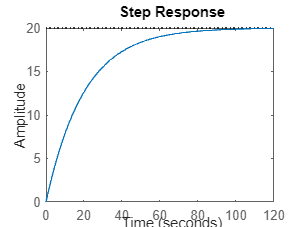

% Ingresso di controllo [N]
u = 1000;

% Risposta al gradino in anello aperto
step(u*plant_tf);

Dalla risposta del sistema in anello aperto, si evince l'assenza di overshoot o di oscillazioni, un comportamento caratteristico dei sistemi dinamici del primo ordine. Pertanto, il sistema raggiunge con successo la velocità costante desiderata di 20 m/s.

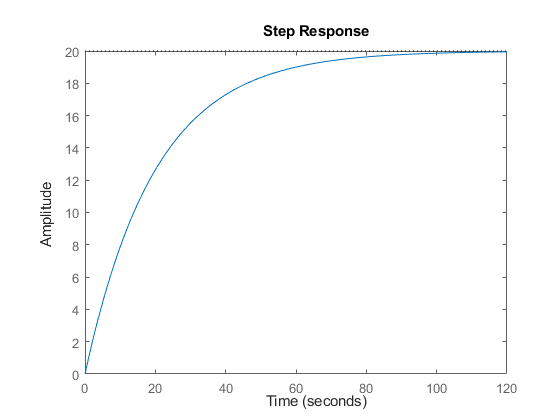

Tuttavia, il tempo impiegato per raggiungere la velocità desiderata di circa 60 secondi è particolarmente lungo. Di conseguenza, si vuole progettare un controllore in retroazione che acceleri significativamente la risposta del sistema senza influire negativamente sugli altri aspetti delle prestazioni dinamiche.

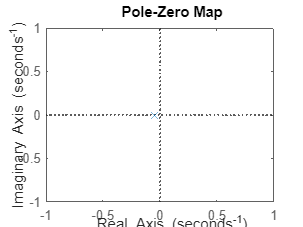

% Collocazione di poli e zeri
pzmap(plant_tf);
axis([-1, 1, -1, 1]);

Dalla mappa poli-zeri si osserva che il sistema in anello aperto si mantiene stabile e privo di oscillazioni perché il suo unico polo è reale e presenta parte reale negativa.

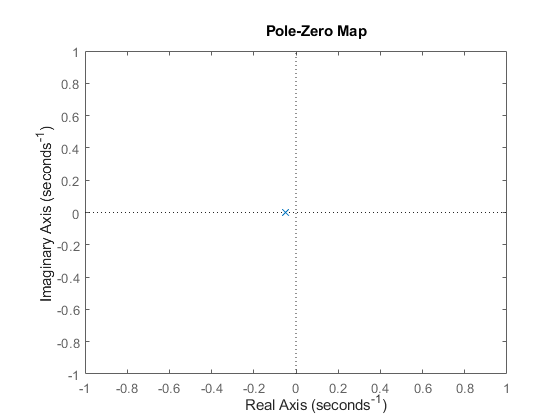

D'altronde, dalla funzione di trasferimento:


$$\textrm{ms}+b=0\Rightarrow s=-\frac{b}{m}$$


La velocità di risposta del sistema è determinata dal modulo di questo polo; in sostanza, un modulo maggiore comporta un raggiungimento più rapido del valore desiderato a regime.

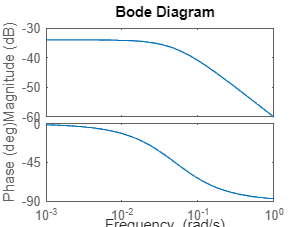

% Diagrammi di Bode
bode(plant_tf);

Per concludere i diagrammi di Bode evidenziano caratteristiche tipiche dei sistemi dinamici del primo ordine, come modulo di -3 dB e fase di -45 deg in corrispondenza di una frequenza di taglio di 0.05 rad/s ed una pendenza di -20 dB/dec ad alte frequenze.

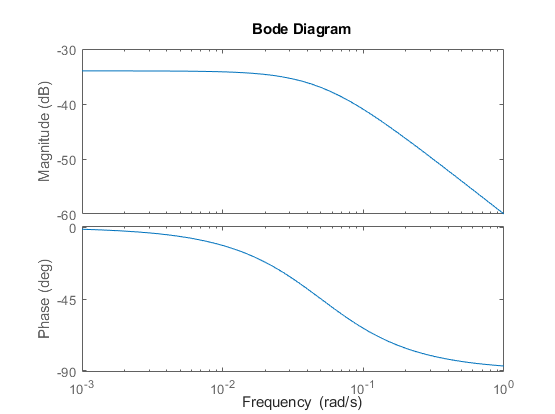

## Controllo del sistema

Una volta implementato il sistema da controllare, è necessario definire il controllore MPC.

### Parametri del controllo

Valori ragionevoli del periodo di campionamento in un sistema di controllo automatico della velocità di crociera sono compresi nell'intervallo che va da 0.1 a 0.5 secondi.

Poiché il primo requisito richiede che il tempo di salita sia inferiore a 5 secondi, noto il periodo di campionamento, un valore congruo dell'orizzonte di predizione può essere ottenuto dalla relazione:


$$t_r \approx T_s \cdot H_p \;\;\;\Rightarrow \;\;H_p =\frac{t_r }{T_s }=\frac{5}{0\ldotp 1}=50$$


L'orizzonte di controllo deve essere molto più piccolo dell'orizzonte di predizione, ad esempio è possibile sceglierlo uguale a 2.

% Periodo di campionamento
Ts = 0.1;   % 10 Hz

% Orizzonte di predizione
Hp = 50;

% Orizzonte di controllo
Hc = 2;

### Definizione del controllore

% Controllore MPC
mpcobj = mpc(plant_ss,Ts);

-->"PredictionHorizon" is empty. Assuming default 10.
-->"ControlHorizon" is empty. Assuming default 2.
-->"Weights.ManipulatedVariables" is empty. Assuming default 0.00000.
-->"Weights.ManipulatedVariablesRate" is empty. Assuming default 0.10000.
-->"Weights.OutputVariables" is empty. Assuming default 1.00000.


### Tuning del controllore

Per comprendere meglio l'impatto dei parametri del controllore sull'uscita del sistema, l'oggetto controllore MPC è stato creato senza specificare gli orizzonti di predizione e di controllo.

L'impiego del tool MPC Designer permette di assistere la progettazione dei controllori nel caso di sistemi dinamici lineari secondo un approccio trial and error, cioè verificando l'impatto della variazione dei parametri di controllo sull'uscita del sistema.

Si inizializza l'ambiente prima importando il controllore dalla voce MPC Structure e poi impostando il riferimento desiderato di 20 m/s modificando lo scenario corrente. Il tool restituisce in automatico l'evoluzione dell'ingresso e dell'uscita del sistema.

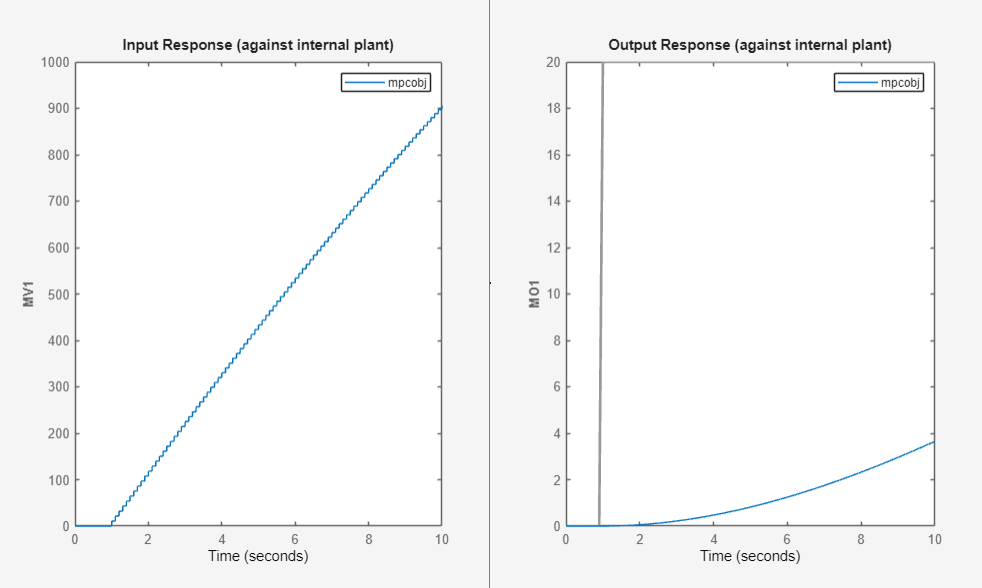

È evidente che il sistema non è in grado di raggiungere il riferimento desiderato di 20 m/s nei primi 10 secondi.

Occorre quindi agira sui parametri di base del controllore MPC.

Per visualizzare meglio l'evoluzione dell'ingresso e dell'uscita è possibile impostare, sempre dallo scenario, una durata della simulazione maggiore, ad esempio di 30 secondi. 

### Tuning dell'orizzonte di predizione

Impostando l'orizzonte di predizione a 50, come calcolato preliminarmente, si ottiene un andamento comparabile a quello di un sistema del secondo ordine, quindi del tutto diverso da quello in anello aperto. Nonostante in circa 20 secondi venga raggiunto il riferimento desiderato, il sistema è ancora troppo lento.

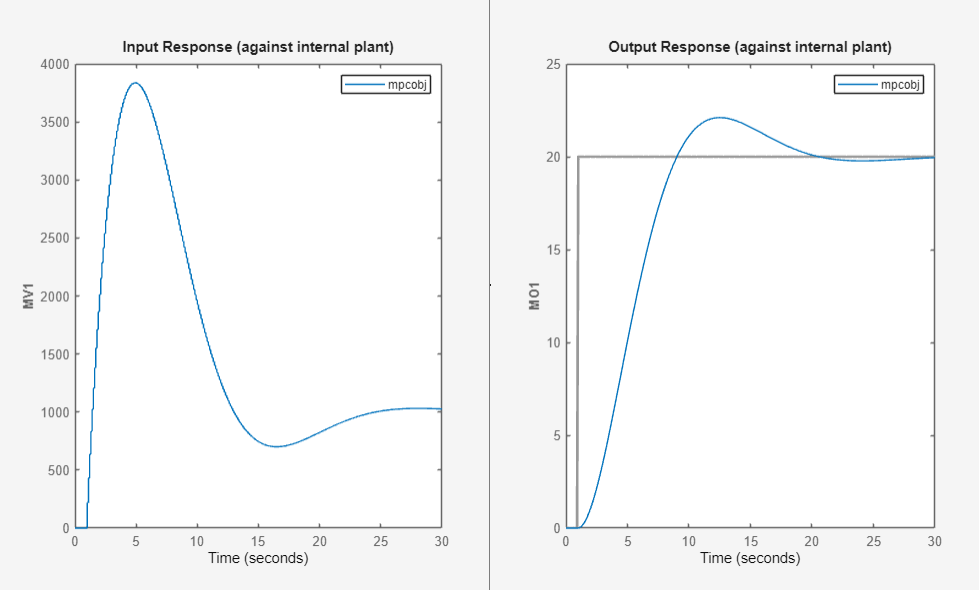

Si ripete il tuning confrontando gli andamenti per diversi valori dell'orizzonte di predizione rispetto a quello di partenza:

- Un valore di 20 rallenta il sistema

- Un valore di 70 previene la comparsa dell'overshoot e migliora di diversi secondi il tempo di salita

- Un valore di 100 peggiora complessivamente le prestazioni

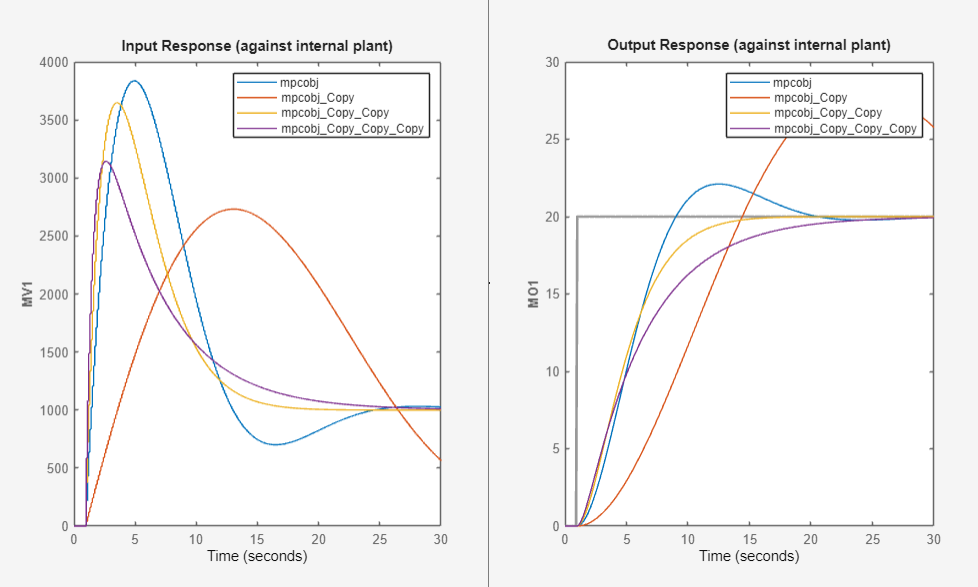

### Tuning dell'orizzonte di controllo

Si ripete il tuning confrontando gli andamenti per diversi valori dell'orizzonte di controllo rispetto a quello di partenza, mantendo invariati gli altri parametri del controllore:

- Un valore di 5 comporta una differenza irrisoria

- Un valore di 10 comporta una differenza ancora irrisoria

- Un valore di 25 comporta una differenza progressivamente irrisoria rispetto ai casi precedenti

- Un valore di 50 comporta una differenza impercettibile rispetto al caso precedente, pur avendone duplicato il valore

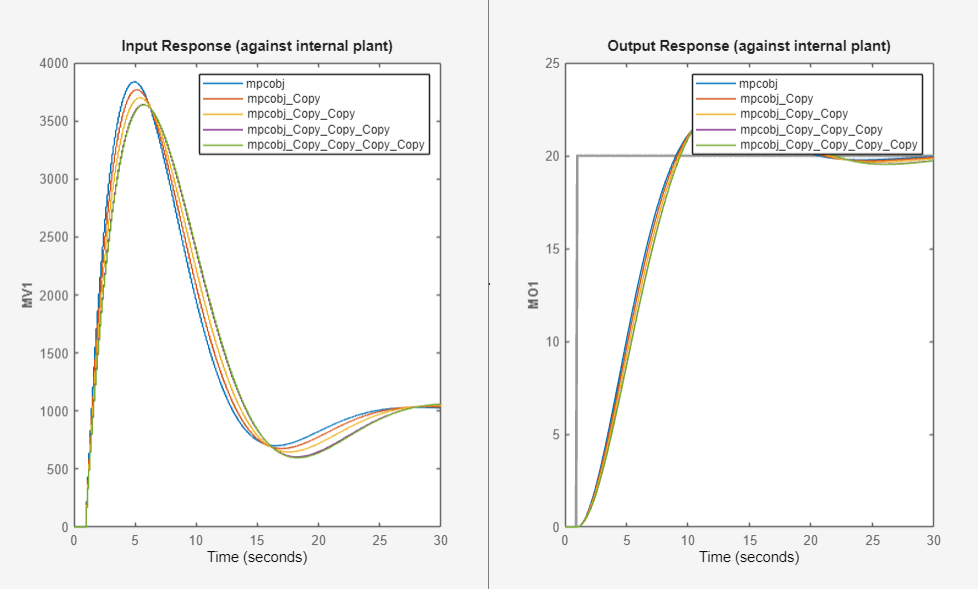

È conveniente mantenere il valore dell'orizzonte di controllo il più piccolo possibile perché le differenze sono impercettibili a discapito di un costo computazionale del che aumenta esponenzialmente all'aumentare. In altre parole, le differenze osservate non rendono giustificabile l'aumento di complessità del controllo che comporta l'aumento del valore dell'orizzonte di controllo.

### Tuning dei pesi

La voce Weights contiene i pesi che vengono assegnati agli input, alla loro variazione ed alle uscite. Poiché si vuole migliorare la risposta del sistema, è ragionevole andare ad agire sul peso associato all'uscita. Si ripete quindi il tuning confrontando gli andamenti per diversi valori dei pesi associati all'uscita, mantendo invariati gli altri parametri del controllore:

- Un peso di 2 migliora l'uscita perché previene l'overshoot e permette di raggiungere il riferimento in circa 10 secondi in meno, inoltre assicura un l'errore a regime nullo

- Un peso di 5 non migliora l'uscita, anzi ne rallenta il raggiungimento del riferimento rispetto al caso precedente

- Un peso di 10 non comporta alcun tipo di cambiamento, pur avendone raddoppiato l'entità

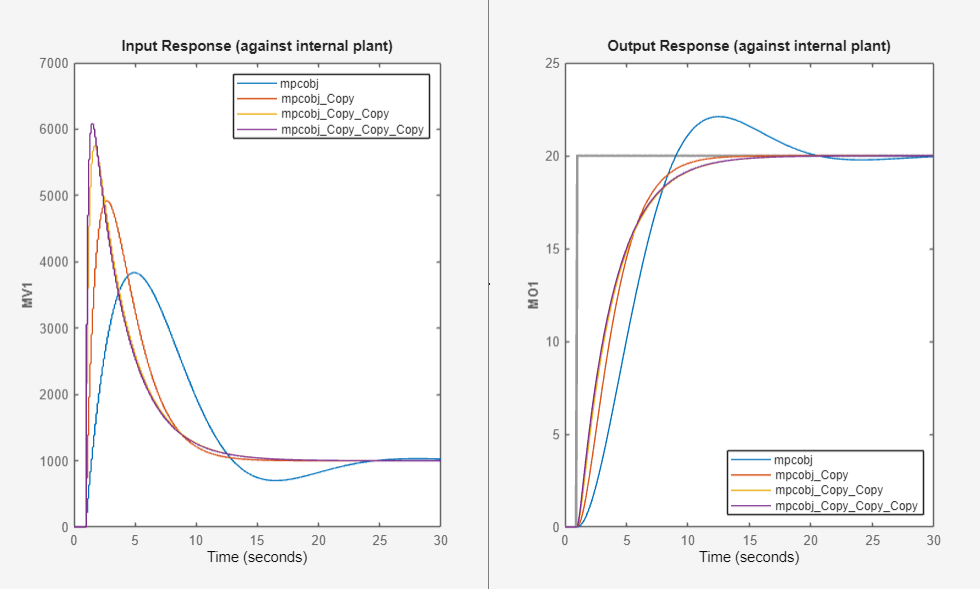

### Tuning dei parametri

Avendo fissato sia l'orizzonte di controllo che il peso associato all'uscita a 2, si può pensare di ripetere il tuning andando a variare nuovamente l'orizzonte di predizione:

- Un valore di 25 previene la comparsa dell'overshoot e rende il sistema estremamente rapido, con un raggiungimento del riferimento desiderato in circa 8 secondi

- Un valore di 20 diminuisce ulteriormente il tempo di salita ma è meno vantaggioso perché (riducendo la finestra di predizione) il controllore non riesce a prevenire la comparsa dell'overshoot, in altre parole nel momento in cui il controllore si accorge dell'overshoot è troppo tardi per agire